# NB-IoT simulation

## ofdm parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=2;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz
L = 1;  % Upsampling factor

## simulation parameters

dataLength=numSC*numSym*2;
randomData=true;
nLoops=1;
filtersOn=false;
plotSpec=true;
maxSNR=25;
perfectChannel=true;
varSNR=false;
varDoppler=false;%vary doppler  shift per loop
flatDoppler=true;%false:let dopplershift go from +dopplershift to 0 to -dopplerlshift over course of signal
dopplerShift=0;
delaySpread=true;

## transmission


%base message
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     1
     0
     1
     0
     0
     1
     0
     0
     1



%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      1
     1
     0
     2
     1
     0
     0
     0
     0
     3


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =   -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i


%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


% numSC=12;% # subcarriers
% numSym=21;% # ofdm symbols
% SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
% t = (0:SPS-1) / samplingRate; %time vector

ofdmSignal = zeros(1, numSym * SPS);
%cpLen=round(SPS/4);%cyclic prefix length
cpLen=5;
if L==1
    t=(symbolDuration/(SPS+cpLen):symbolDuration/(SPS+cpLen):(symbolDuration)*numSym);%time for each sample

else
    t=(symbolDuration/(SPS+cpLen+(L-1)*(SPS+cpLen)):symbolDuration/(SPS+cpLen+(L-1)*(SPS+cpLen)):(symbolDuration)*numSym);%time for each sample

end


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =   -0.7071 + 0.7071i   0.7071 + 0.7071i
  -0.7071 + 0.7071i  -0.7071 + 0.7071i
   0.7071 + 0.7071i   0.7071 - 0.7071i
   0.7071 - 0.7071i  -0.7071 - 0.7071i
  -0.7071 + 0.7071i  -0.7071 - 0.7071i
   0.7071 + 0.7071i   0.7071 + 0.7071i
   0.7071 + 0.7071i   0.7071 + 0.7071i
   0.7071 + 0.7071i  -0.7071 + 0.7071i
   0.7071 + 0.7071i   0.7071 + 0.7071i
  -0.7071 - 0.7071i   0.7071 + 0.7071i


%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =   -0.1179 - 0.1179i   0.3062 + 0.0589i
  -0.1610 + 0.1294i   0.2199 + 0.2630i
  -0.1179 + 0.3536i   0.1179 - 0.2357i
   0.1610 + 0.1926i   0.1021 + 0.1768i
  -0.1179 - 0.1179i  -0.3062 + 0.0589i


timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =   -0.1179 - 0.1179i   0.3062 + 0.0589i
  -0.1610 + 0.1294i   0.2199 + 0.2630i
  -0.1179 + 0.3536i   0.1179 - 0.2357i
   0.1610 + 0.1926i   0.1021 + 0.1768i
  -0.1179 - 0.1179i  -0.3062 + 0.0589i
   0.1179 + 0.3536i   0.1179 + 0.2357i
  -0.3220 + 0.0000i   0.2199 - 0.2630i
  -0.0431 + 0.3967i  -0.1021 + 0.1768i
  -0.1179 - 0.1179i  -0.3536 + 0.2357i
   0.0431 - 0.4830i   0.0158 - 0.1452i



timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =   -0.1179 - 0.1179i
  -0.1610 + 0.1294i
  -0.1179 + 0.3536i
   0.1610 + 0.1926i
  -0.1179 - 0.1179i
   0.1179 + 0.3536i
  -0.3220 + 0.0000i
  -0.0431 + 0.3967i
  -0.1179 - 0.1179i
   0.0431 - 0.4830i


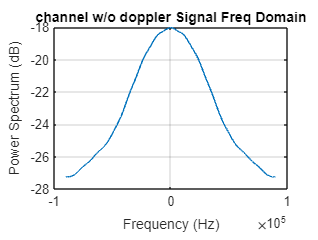

% plot ofdm signal

if plotSpec 
figure
window=hamming(7);
spectrogram(timeDomainSymbols,window,round(length(window)/2),BW)
end

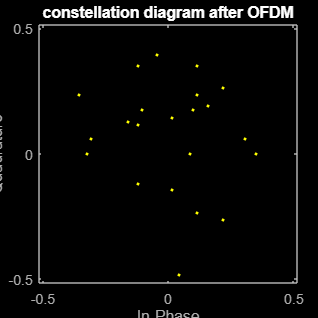


figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

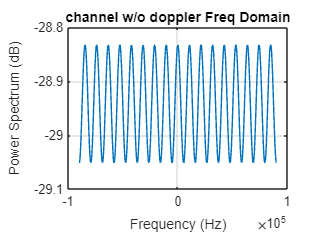


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

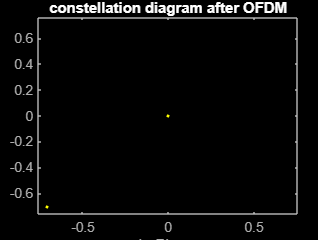

%upsampling
%L = 2;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

%txSignalUpsampled = upsample(timeDomainSymbols, L);
padFactor = L; % Adjust this factor to get more or less padding
txSignalUpsampled = [timeDomainSymbols; zeros(length(timeDomainSymbols)*(padFactor-1),1)];


rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

if filtersOn
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;

end

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

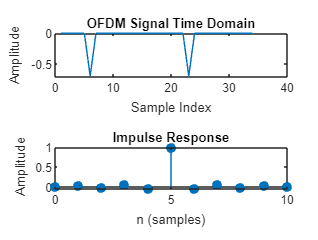


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

een vaste doppler shift zal in deze simulatie geen verschil maken, heel het signaal verschuift in freq domein maar uiteindelijk wordt de 180 kHz toch in 12 carriers opgesplitst,

varierende doppler shift zal wss wel effect hebben?

h =     1.0000    0.7000    0.4000    0.2000


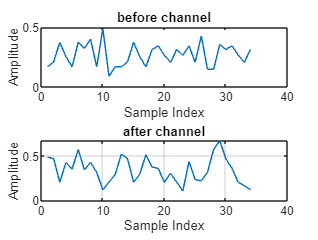

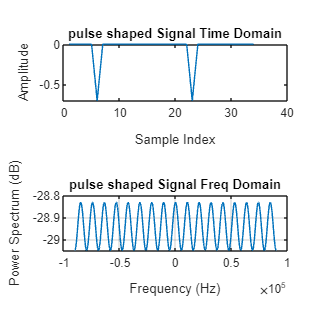

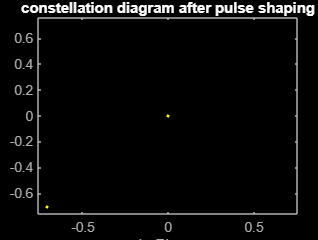

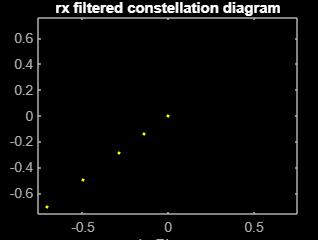

for counter=1:nLoops

if flatDoppler
    freqShift=dopplerShift;
else
    freqShift=linspace(-dopplerShift,dopplerShift,length(t));

end

if varDoppler
    dopplerEffect = exp(1i * 2 * pi * (freqShift+counter*50).* t);
else
    dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
end


txSignalDopplerShifted = transpose(txSignalUpsampled) .* (dopplerEffect);

if varSNR
    SNR=maxSNR-(counter-1);
else 
    SNR=maxSNR;
end
if perfectChannel
    rxSignal=txSignalDopplerShifted;
else
    rxSignal=awgn(txSignalDopplerShifted,SNR);
end

if delaySpread
    Ts = 1/samplingRate; % Sampling period (s)
    % delayTimes = [0, 1, 2, 3] * Ts;  % Delays in seconds
    % gains = [1, 0.5, 0.3, 0.1];  % Corresponding path gains
    delaySamples = [0, 1, 2, 3];       % Delays in samples
    gains = [1, 0.7, 0.4, 0.2];        % Corresponding path gains
   % Initialize the CIR vector
    maxDelaySamples = max(delaySamples);
    h = zeros(1, maxDelaySamples + 1);  % CIR vector initialized with zeros

    % Set the non-zero values for the delays
    for k = 1:length(delaySamples)
        h(delaySamples(k) + 1) = gains(k);  % Set the CIR value at the corresponding index
    end
    h
    rxSignalSpread = conv(rxSignal, h, 'same');
else
    rxSignalSpread=rxSignal;
end



if counter==nLoops %only plot in last loop
    % Plot the time domain signal after channel
    figure;
    subplot(2,1,1);
    grid on
    title('before channel');
    plot(abs(txSignalShaped));
    title('before channel');
    xlabel('Sample Index');
    ylabel('Amplitude');

    subplot(2,1,2);
    plot(abs(rxSignalSpread));
    grid on
    title('after channel');
    xlabel('Sample Index');
    ylabel('Amplitude');
    figure
    scatterplot(rxSignalSpread)
    title('constellation diagram after channel');
    
    % Plot the time domain signal
    % figure;
    % plot(real(rxSignal));
    % title('channel Signal Time Domain');
    % xlabel('Sample Index');
    % ylabel('Amplitude');
    
    figure
    [pxx,f] = pspectrum(txSignalUpsampled,samplingRate);
    plot(f,pow2db(pxx))
    grid on
    title('channel w/o doppler Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')

    figure
    [pxx2,f2] = pspectrum(rxSignalSpread,samplingRate);
    plot(f2,pow2db(pxx2))
    grid on
    title('channel w/o doppler Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## receiver

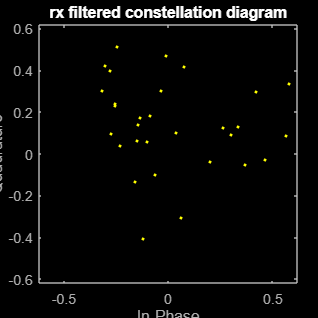

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
if filtersOn
    matchedFilter = rcosdesign(rolloff, span, L);
    rxSignalFiltered = conv(rxSignalSpread, matchedFilter, 'same');
else
    rxSignalFiltered = rxSignalSpread;

end

rxSignalFiltered;

%downsample
rxSignalDownsampled = downsample(rxSignalFiltered, L);
if counter==nLoops
    figure;
    scatterplot(rxSignalFiltered);
    title('rx filtered constellation diagram');
end

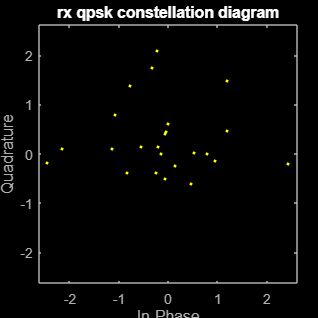


%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignalDownsampled, [], numSym);
%rxSymbolsWithCP
rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);

if counter==nLoops
    figure;
    scatterplot(rxQPSKSymbols);
    title('rx qpsk constellation diagram');
end


% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(transpose(demodulatedBits)~=transpose(messageBits(1:dataLength)));
nbiot_ber(counter)=errors/dataLength;

symbolRate=samplingRate/SPS;
bitRate =  2*12*symbolRate;

SNR_linear = 10^(SNR / 10);
%Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

EbN0_sim(counter)=10*log10(SNR_linear*samplingRate/bitRate);


end
nbiot_ber
EbN0_sim

nbiot_ber = 0.4583

EbN0_sim = 21.9897

## ber

[https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html](https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html)

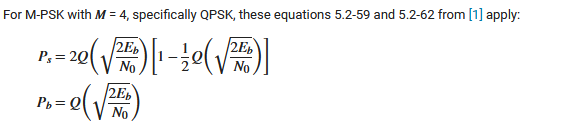

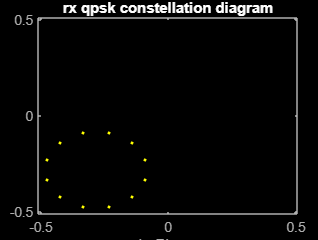


EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(transpose(EbN0),ber,'*')
hold on
semilogy(transpose(EbN0_sim),nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on